clc;
clf;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'train';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_colon_9_26.csv';

arm = 'psm3_fena';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

if strcmp(test_folder, 'test')
%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];
      joint_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/joints/'];
      torque_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/', 'lstm', network];
else
    joint_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/joints/'];
    torque_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/', 'lstm', network];
end

joint_data = readmatrix([joint_path, 'interpolated_all_joints.csv']);
torque_data = readmatrix(torque_path);

measured_torque = joint_data(:,14:16);
fs_pred_torque = torque_data(:,2:4);
loss(file+1) = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),:) - fs_pred_torque).^2)));
loss_joint1 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),1) - fs_pred_torque(:,1)).^2)));
loss_joint2 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),2) - fs_pred_torque(:,2)).^2)));
loss_joint3 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),3) - fs_pred_torque(:,3)).^2)));

[minSix, maxSix] = bounds(measured_torque(:,1));
bound1 = abs(maxSix - minSix)

bound1 = 6.3019

[minSix, maxSix] = bounds(measured_torque(:,2));
bound2 = abs(maxSix - minSix)

bound2 = 5.9704

[minSix, maxSix] = bounds(measured_torque(:,3));
bound3 = abs(maxSix - minSix)

bound3 = 10.8708



figure()
tcl = tiledlayout(3,1,'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('FS Torque Mesured vs. Prediction, Training, RMSE = %.4f', loss(1)))


nexttile
plot(joint_data(1:0.05*length(joint_data), 1), joint_data(1:0.05*length(joint_data),14), 'b')

hold on
title(sprintf('Joint 1, RMSE = %.4f, RMSE/PP =  %.2f%%', loss_joint1, loss_joint1/bound1*100))
plot(torque_data(1:0.05*length(joint_data), 1), torque_data(1:0.05*length(joint_data),2), 'r')

hold off

nexttile
plot(joint_data(1:0.05*length(joint_data), 1), joint_data(1:0.05*length(joint_data),15), 'b')

hold on
title(sprintf('Joint 2, RMSE = %.4f, RMSE/PP =  %.2f%%', loss_joint2, loss_joint2/bound2*100))
plot(torque_data(1:0.05*length(joint_data), 1), torque_data(1:0.05*length(joint_data),3), 'r')


nexttile
plot(joint_data(1:0.05*length(joint_data), 1), joint_data(1:0.05*length(joint_data),16), 'b')

hold on
title(sprintf('Joint 3, RMSE = %.4f, RMSE/PP =  %.2f%%', loss_joint3, loss_joint3/bound3*100))
plot(torque_data(1:0.05*length(joint_data), 1), torque_data(1:0.05*length(joint_data),4), 'r')

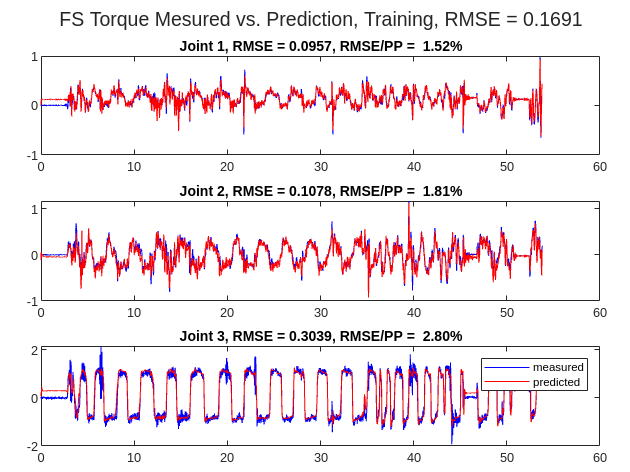

legend('measured', 'predicted')
hold off

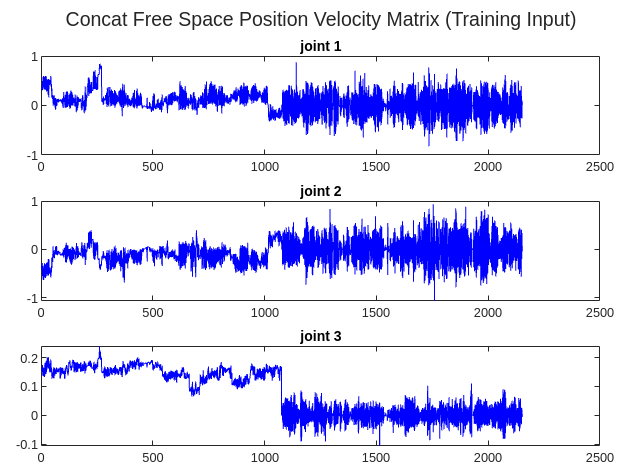


clf;

figure()
tcl = tiledlayout(3,1,'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Concat Free Space Position Velocity Matrix (Training Input)'))

nexttile
plot(0.005*(1:2*length(joint_data(:,1))), cat(1,joint_data(:,2),joint_data(:,8)), 'b')
hold on
title('joint 1')
hold off

nexttile
plot(0.005*(1:2*length(joint_data(:,1))), cat(1,joint_data(:,3),joint_data(:,9)), 'b')
hold on
title('joint 2')

nexttile
plot(0.005*(1:2*length(joint_data(:,1))), cat(1,joint_data(:,4),joint_data(:,10)), 'b')
hold on
title('joint 3')



clf;

figure()
tcl = tiledlayout(3,1,'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Free Space Torque Matrix (Training object)'))

nexttile
% plot(joint_data(:,1), joint_data(:,14), 'b')
plot(joint_data(1:0.05*length(joint_data),1), joint_data(1:0.05*length(joint_data),14), 'b')

hold on
title('joint 1')
hold off

nexttile

% plot(joint_data(:,1), joint_data(:,15), 'b')
plot(joint_data(1:0.05*length(joint_data),1), joint_data(1:0.05*length(joint_data),15), 'b')

hold on
title('joint 2')

nexttile
% plot(joint_data(:,1), joint_data(:,16), 'b')
plot(joint_data(1:0.05*length(joint_data),1), joint_data(1:0.05*length(joint_data),16), 'b')

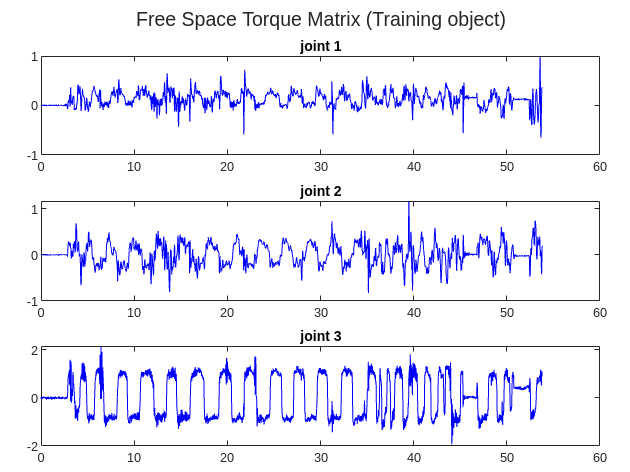

hold on
title('joint 3')